# Homework 6

Math 3607, Autumn 2021

Xiaoya Gao

Gao.1666

## Problem 1 (Understanding matrix multiplication)

## Part(a) 

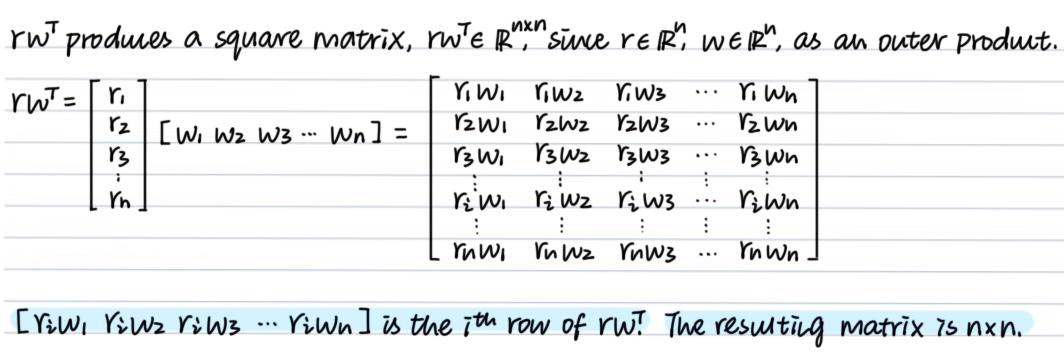

## Part(b) 

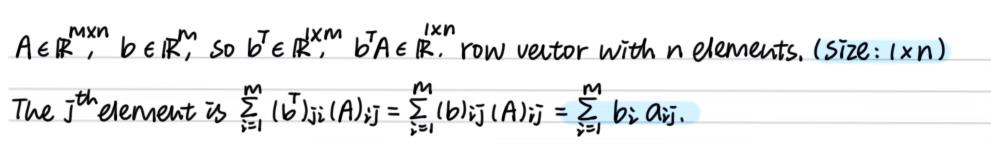

## Part(c)

##  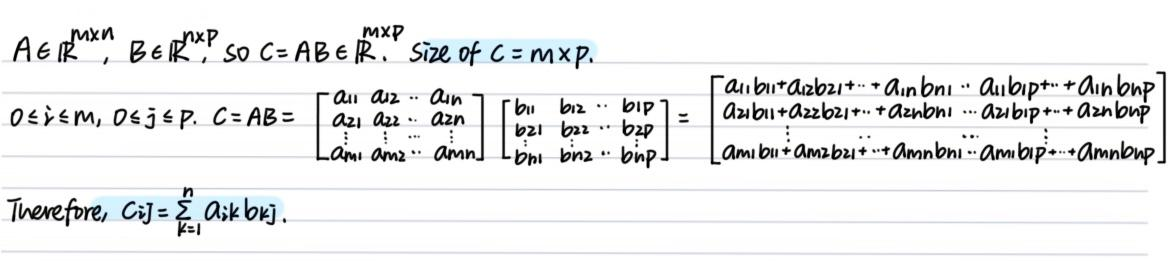

## Part(d)

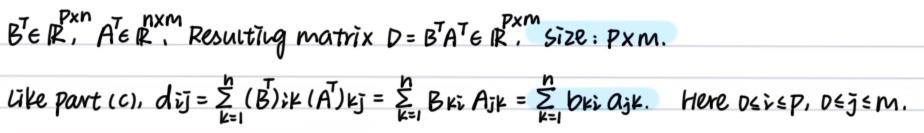

## Part(e)

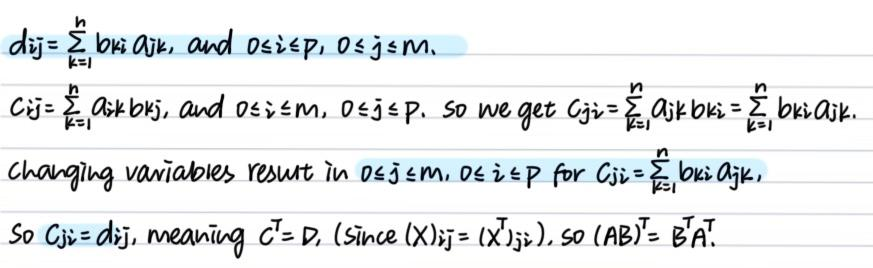

## Part(f)

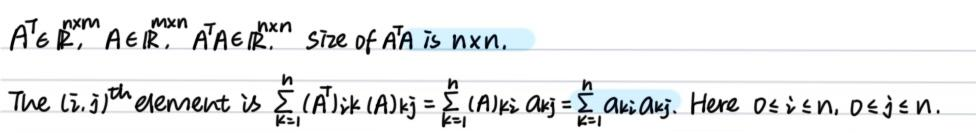

## Part(g)

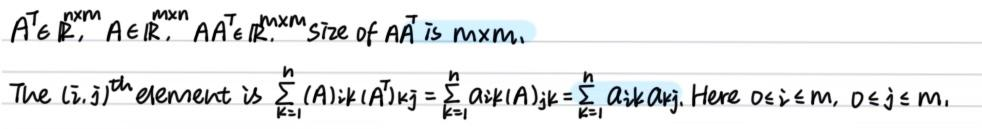

## Part(h)

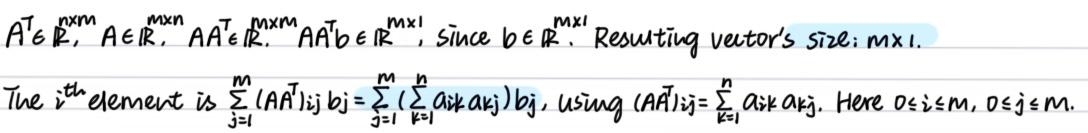

## Problem 2 (Gram-Schmidt in MATLAB)

Reference: LM p.1616; lecture 17; 

A = reshape([4:24],7,3); % random 7-by-3 matrix for test
[m,n] = size(A);


[Q,R] = GramSchmidt(A);

% test the orthogonality for thin QR; reference: lecture 17
norm(Q' * Q - eye(n))

ans = 1.2330

norm(Q * R - A)

ans = 8.2481e-14

And we test the orthogonality again with [Q,R] = qr(A,0).

[Q,R] = qr(A,0);

norm(Q' * Q - eye(n))

ans = 4.9043e-16

norm(Q * R - A)

ans = 1.3345e-14

## Problem 3 (Periodic fit)

## Part(a)

clf
t = linspace(0,2*pi,200)';
b = exp(sin(t-1));
n = length(t);

V1 = t.^(0:6);
c = V1\b; % coefficients of the least square fit

## Part(b)

V2 = [ones(n,1) cos(t) sin(t) cos(2*t) sin(2*t)];
d = V2\b; % coefficients of the least square fit

## Part(c)

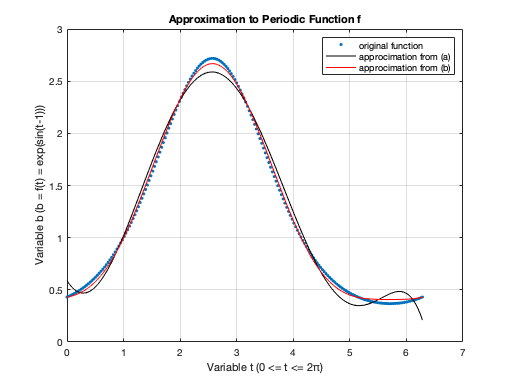

p = @(t) polyval(flip(c),t);
q = @(t) d(1)+d(2)*cos(t)+d(3)*sin(t)+d(4)*cos(2*t)+d(5)*sin(2*t);



plot(t,b,'.') % original function 
hold on

fplot(p,[0 2*pi],'k-') % approcimation from (a)
hold on

fplot(q,[0 2*pi],'r-') % approcimation from (b)

xlabel('Variable t (0 <= t <= 2π)')
ylabel('Variable b (b = f(t) = exp(sin(t-1)))')
title('Approximation to Periodic Function f')
legend('original function', 'approcimation from (a)', 'approcimation from (b)')
grid on

## Problem 4 (Adapted from FNC 3.3.3)

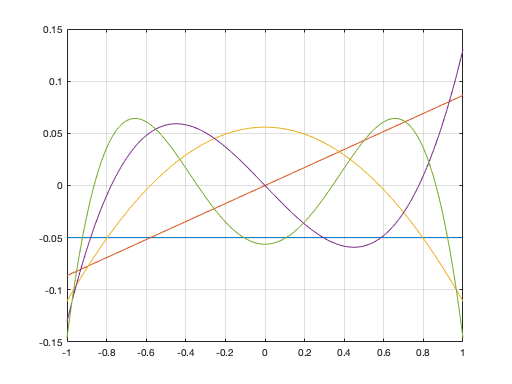

clf
x = linspace(-1,1,400)'; % stores 400 equally spaced points between [-1,1]
V = x.^[0:4]; % vandermonde-type matrix with m = 600,n = 5

[Q,R] = qr(V,0);
for k = 1:5
    plot(x,Q(:,k)) % plots every column of Q
    hold on
end
grid on

## Problem 5 (Visualizing matrix norms) 

## Part(a)

The function visMatrixForm(A,p) is embedded at the end of the livescript.

## Part(b)

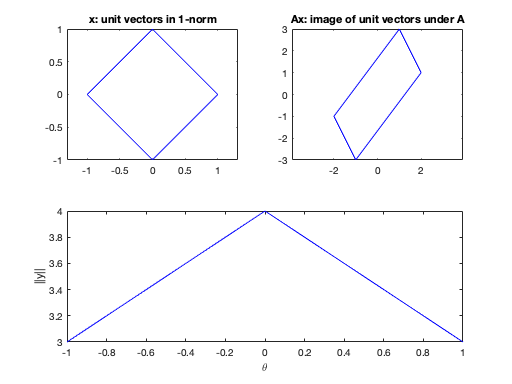

 p = 1
 approx. norm: 4.0000000000000000
 actual  norm: 4.0000000000000000


A = [2,1; 1,3];
visMatrixForm(A,1)

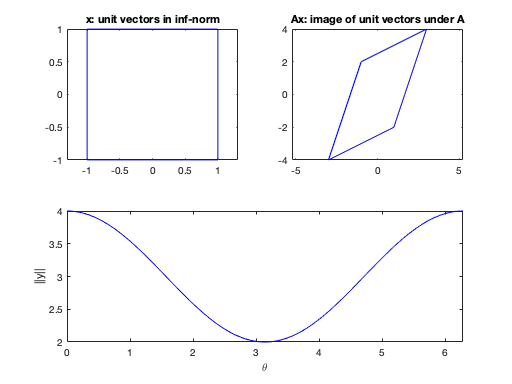

 p = inf
 approx. norm: 4.0000000000000000
 actual  norm: 4.0000000000000000


visMatrixForm(A,inf)

function visMatrixForm(A,p)
% VISMATRIXFORM = visMatrixForm(A,p)
% approximates p-norm of A and generates a figure
% illustrating the definition of matrix form
% Input:
%    A  2-by-2 matrix
%    p  a number which can be either 1,2 or inf

    if p == 1
        theta = [-1,0,1];
        % abs(u_1) + abs(u_2) = 1
        X = [theta; 1-abs(theta)]; % unit vectors in 1-norm
        Y = A*X; % images of x under A
        norm_Y = sum(abs(Y)); % norm of vectors y
    
    elseif p == 2
        theta = linspace(0, 2*pi, 361);
        % (u_1)^2 + (u_2)^2 = 1
        X = [cos(theta); sin(theta)]; % unit vectors in 2-norm
        Y = A*X;
        norm_Y = sqrt(sum(Y.^2, 1));

    elseif p == inf
        theta = linspace(0, 2*pi, 361);
        % MAX {(u_1), (u_2)} = 1
        X = [cos(theta); ones(1,361)]; % unit vectors in inf-norm
        Y = A*X;
        norm_Y = max(abs(Y)); 

    end

    % visualization
        clf
        subplot(2,2,1)
        plot(X(1,:), X(2,:),'b-'), axis equal
        if p == 1
            hold on
            theta = [-1,0,1];
            % u_2 should be +/-
            X = [theta; -1+abs(theta)];
            plot(X(1,:), X(2,:),'b-')
            title('x: unit vectors in 1-norm')

        elseif p == inf
            hold on
            theta = linspace(0, 2*pi, 361);
            % MAX {u_1,u_2} = 1
            X = [ones(1,361); cos(theta)]; 
            plot(X(1,:), X(2,:),'b-')
            hold on
            X = [-1*ones(1,361); cos(theta)]; 
            plot(X(1,:), X(2,:),'b-')
            hold on
            X = [-1*ones(1,361); -1*cos(theta)]; 
            plot(X(1,:), X(2,:),'b-')
            hold on
            X = [cos(theta); -1*ones(1,361)]; 
            plot(X(1,:), X(2,:),'b-')
            title('x: unit vectors in inf-norm')
        else
            title('x: unit vectors in 2-norm')
        end



        subplot(2,2,2)
        plot(Y(1,:), Y(2,:),'b-'), axis equal
        title('Ax: image of unit vectors under A')
        if p == 1
            hold on
            theta = [-1,0,1];
            % u_2 should be +/-
            X = [theta; -1+abs(theta)];
            Y = A*X;
            plot(Y(1,:), Y(2,:),'b-')

        elseif p == inf
            hold on
            theta = linspace(0, 2*pi, 361);
            % MAX {u_1,u_2} = 1
            X = [ones(1,361); cos(theta)];
            Y = A*X; 
            plot(Y(1,:), Y(2,:),'b-')
            hold on
            X = [-1*ones(1,361); cos(theta)]; 
            Y = A*X; 
            plot(Y(1,:), Y(2,:),'b-')
            X = [-1*ones(1,361); -1*cos(theta)];
            hold on
            Y = A*X; 
            plot(Y(1,:), Y(2,:),'b-')
            X = [cos(theta); -1*ones(1,361)]; 
            Y = A*X; 
            plot(Y(1,:), Y(2,:),'b-')
        end



        subplot(2,1,2)
        plot(theta, norm_Y,'b-'), axis tight
        xlabel('\theta') 
        ylabel('||y||')

    % matrix norm approximation (and comparison)
    if p == 1
        fprintf(' p = 1\n')
        fprintf(' approx. norm: %18.16f\n', max(norm_Y))
        fprintf(' actual  norm: %18.16f\n', norm(A, 1))
    elseif p == 2
        fprintf(' p = 2\n')
        fprintf(' approx. norm: %18.16f\n', max(norm_Y))
        fprintf(' actual  norm: %18.16f\n', norm(A, 2))
    elseif p == inf
        fprintf(' p = inf\n')
        fprintf(' approx. norm: %18.16f\n', max(norm_Y))
        fprintf(' actual  norm: %18.16f\n', norm(A, inf))
    end

end

function [Q,R] = GramSchmidt(A)
% GRAMSCHMIDT [Q,R] = GramSchmidt(A)
% computes thin QR factorization for matirx A
% Input:
%    A  coefficient matrix (m-by-n and m >= n)
% Output:
%    Q  orthogonal matrix (m-by-n)
%    R  upper triangular matrix (n-by-n, QR = A)

    [m,n] = size(A); % returns size [m n]
    Q = zeros(m,n); % preallocates m-by-n matrix Q
    R = zeros(n,n); % preallocates n-by-n matrix R
    B = A; % makes some matrix B = A first

    for k = 1:n  % a_k and q_k represent the columns

        % b = a - R(k-1,k)*q_k-1 - R(k-2,k)*q_k-2...
        B(:,k) = A(:,k) - B(:,1:k-1) * R(1:k-1,k);

        % R is an upper triangular matrix
        R(k,k+1:n) = Q(:,k)' * A(:,k+1:n);
        R(k,k) = norm((B(:,k) - B(:,1:k-1) * R(1:k-1,k)),2);
        
        % q = b/R(k,k)
        B(:,k) = B(:,k)/R(k,k); % uses in the next loop
        Q = B;
    end
end